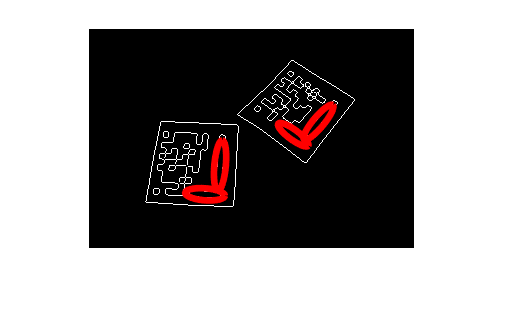

%TestImage1 = imread('im2.jpg');
%TestImage1 = imread('im4.png');
TestImage1 = imread('image1.png');
%TestImage1 = imread("training_1.jpg");

TestImage1 = imsharpen(TestImage1);

TestImage1 = imresize(TestImage1, 0.5);
%TestImage1 = imrotate(TestImage1, -45);

TestG = rgb2gray(TestImage1);



bw = edge(TestG);

MaxPixels = 10;



[L,num] = bwlabel(bw);

counts = sum(bsxfun(@eq,L(:),1:num));
B1 = bsxfun(@eq,L,permute(find(counts>MaxPixels),[1 3 2]));
L2 = sum(B1,3)>0;

imshow(L2);

%Find regions
s = regionprops(L2,{...
    'Centroid',...
    'MajorAxisLength',...
    'MinorAxisLength',...
    'Orientation'});

TotalShapes = length(s);

GuidelinesS = struct;
GuidelinesL = struct;
Cornerstones = struct;

% GuidelinesS.Centroid = [0 0];
% GuidelinesS.MajorAxisLength = 0;
% GuidelinesS.MajorAxisLength = 0;
% GuidelinesS.Orientation = 0;

MinSRatio = 3;
MaxSRatio = MinSRatio + 6;

PotentialGuideS = 0;
PotentialGuideL = 0;
PotentialCornerstones = 0;

for i = 1:TotalShapes
    Shape = s(i);
    ShapePos = Shape.Centroid;
    ShapeLength = Shape.MajorAxisLength;
    ShapeWidth = Shape.MinorAxisLength;
    ShapeAngle = Shape.Orientation;
    
    %Get Ratio
    ShapeRatio = ShapeLength/ShapeWidth;
    
    %Store Guides
    if ShapeRatio > MinSRatio && ShapeRatio < MaxSRatio 
        PotentialGuideS = PotentialGuideS + 1;

        GuidelinesS(PotentialGuideS).Centroid = ShapePos;
        GuidelinesS(PotentialGuideS).MajorAxisLength = ShapeLength;
        GuidelinesS(PotentialGuideS).MinorAxisLength = ShapeWidth;
        GuidelinesS(PotentialGuideS).Orientation = ShapeAngle;
    
    else
        %Check cornerstones
        if ShapeRatio > 0.7 && ShapeRatio < 1.2
            PotentialCornerstones = PotentialCornerstones + 1;
            
            Cornerstones(PotentialCornerstones).Centroid = ShapePos;
            Cornerstones(PotentialCornerstones).MajorAxisLength = ShapeLength;
            Cornerstones(PotentialCornerstones).MinorAxisLength = ShapeWidth;
            Cornerstones(PotentialCornerstones).Orientation = ShapeAngle;
        end

    end
end

TotalMarkers = 0;
ConfirmedMarkers = struct;

%Verify Shapes
for j = 1:PotentialGuideS
    Shape = GuidelinesS(j);
    ShapePos = Shape.Centroid;
    ShapeLength = Shape.MajorAxisLength;
    ShapeWidth = Shape.MinorAxisLength;
    ShapeAngle = Shape.Orientation;
    
    for k = 1:PotentialGuideS
        Shape2 = GuidelinesS(k);
        ShapePos2 = Shape2.Centroid;
        ShapeLength2 = Shape2.MajorAxisLength;
        ShapeWidth2 = Shape2.MinorAxisLength;
        ShapeAngle2 = Shape2.Orientation;
        
        dGuide = norm(ShapePos - ShapePos2);
        dAngle = abs(ShapeAngle - ShapeAngle2);
        
        Min = 2.5*ShapeWidth;
        Max = 7*ShapeWidth;
        
        if dGuide >=  Min && dGuide <  Max ...
            && dAngle > 75 && dAngle < 100
        
            TotalMarkers = TotalMarkers + 1;
            
            ConfirmedMarkers(TotalMarkers).Centroid = ShapePos;
            ConfirmedMarkers(TotalMarkers).MajorAxisLength = ShapeLength;
            ConfirmedMarkers(TotalMarkers).MinorAxisLength = ShapeWidth;
            ConfirmedMarkers(TotalMarkers).Orientation = ShapeAngle;
        end
        
    end
    
end

ConfirmedCornerstones = zeros(100, 3);
ConfirmedCorner = 0;

%Verify Cornerstones
for Apex = 1:PotentialCornerstones
    Shape = Cornerstones(Apex);
    ShapePos = Shape.Centroid;
    
    for CornerA = 1:PotentialCornerstones
        ShapeA = Cornerstones(CornerA);
        ShapePosA = ShapeA.Centroid;
        
        for CornerB = 1:PotentialCornerstones
            ShapeB = Cornerstones(CornerB);
            ShapePosB = ShapeB.Centroid;
            
            dApexA = norm(ShapePos - ShapePosA);
            dApexB = norm(ShapePos - ShapePosB);
            dCorner = norm(ShapePosA - ShapePosB);
            
            Angle = acos((dApexA^2 + dApexB^2 - dCorner^2)/(2*dApexA*dApexB))*180/pi;
            
            Max = Shape.MinorAxisLength*10;
            Min = Shape.MinorAxisLength*6;
            
            MaxC = Shape.MinorAxisLength*1;
            MinC = Shape.MinorAxisLength*6;
            
            if Angle > 75 && Angle < 100 ...
                    && dApexA > Min && dApexA < Max ...
                        && dApexB > Min && dApexB < Max ...
                            && dCorner > MinC && dCorner < MaxC
                ConfirmedCorner = ConfirmedCorner + 1;
                ConfirmedCornerstones(ConfirmedCorner, :) = [Apex CornerA CornerB];
            end
        end
    end
end

t = linspace(0,2*pi,50);

s = ConfirmedMarkers;

hold on
for k = 1:length(s)
    a = s(k).MajorAxisLength/2;
    b = s(k).MinorAxisLength/2;
    Xc = s(k).Centroid(1);
    Yc = s(k).Centroid(2);
    phi = deg2rad(-s(k).Orientation);
    x = Xc + a*cos(t)*cos(phi) - b*sin(t)*sin(phi);
    y = Yc + a*cos(t)*sin(phi) + b*sin(t)*cos(phi);
    plot(x,y,'r','Linewidth',5)
end
hold off